close('all'); clear; clc;
setmadsympath();

## Geometry

The Sharp model considers a left-handed frame (North, West, Down).

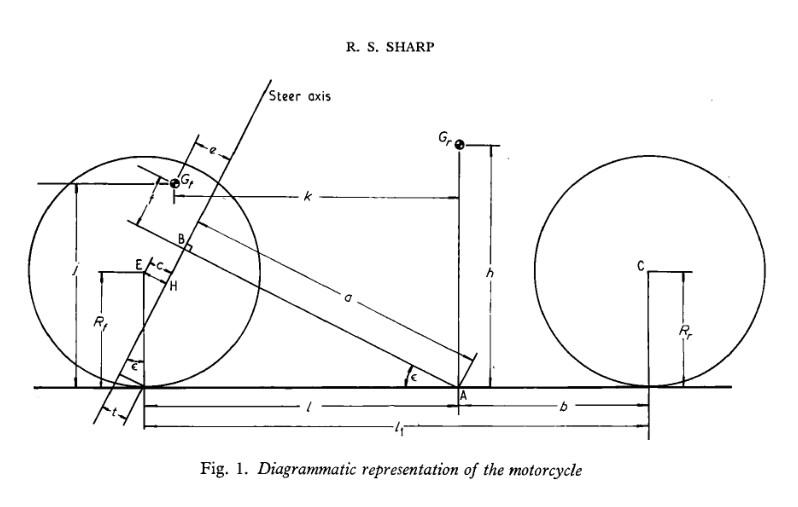

Create the caster frame:

caster = newparams('varepsilon');
N = Frame;
Nc = N.orientNew('y',caster);

Solve for the front wheelbase $l$:

[a,an,l] = newparams('a','a_n','l');
Pa = Point;
Pb = Pa.locateNew(a*Nc.x);
l = solve(cos(caster) == a/(l + an/cos(caster)),l)

$$l = \frac{a-a_{n}}{\cos\left(\varepsilon \right)}$$

Locate the front wheel center $E$:

rf = newparams('r_f');
E = Pa.locateNew(l*N.x - rf*N.z);
rE = E.posFrom

$$rE = \left[\begin{array}{c} \frac{a-a_{n}}{\cos\left(\varepsilon \right)}\\ 0\\ -r_{f} \end{array}\right]$$

Now locate the front wheel center relative to the intersection between the front chassis chord and the steering axis:

rBE = simplify(expand(Ry(caster).'*E.posFrom(Pb)));
lx = rBE(1)

$$lx = r_{f}\,\sin\left(\varepsilon \right)-a_{n}$$

lz = rBE(3)

$$lz = -\frac{r_{f}\,{\cos\left(\varepsilon \right)}^{2}-a\,\sin\left(\varepsilon \right)+a_{n}\,\sin\left(\varepsilon \right)}{\cos\left(\varepsilon \right)}$$

Now solve for the front chassis chord $a$ and the height $f$ of the front chassis mass center in the caster frame to obtain a simplifying substitution for $l_{z}$:

[e,f,j,k] = newparams('e','f','j','k');
Gfa = Pa.locateNew(k*N.x - j*N.z);
Gf = Pb.locateNew(e*Nc.x + f*Nc.z);
sol_af = solve(Gf.posFrom(Gfa) == 0,[a,f]);
lz_sub = simplify(expand(subs(lz,a,sol_af.a)))

$$lz\_sub = -\frac{j\,{\cos\left(\varepsilon \right)}^{2}-j+r_{f}\,{\cos\left(\varepsilon \right)}^{2}+a_{n}\,\sin\left(\varepsilon \right)+e\,\sin\left(\varepsilon \right)-k\,\cos\left(\varepsilon \right)\,\sin\left(\varepsilon \right)}{\cos\left(\varepsilon \right)}$$

clearvars -except a an l rf caster lx lz e f j k sol_af;

## Joint coordinates

Translation of the motorcycle origin $A$:

tstart = tic;
[x,y,yaw,lean,steer,pitch_r,yaw_f,lean_f,pitch_f] = ...
    newDynamicVariables('x','y','psi','varphi','delta','theta_r','psi_f','varphi_f','theta_f');
q = Coordinates([x,y,yaw,lean,steer,pitch_r,pitch_f],[yaw_f,lean_f]);

## Quasi-velocities

u_ind = newDynamicVariables('u',1:5);
u_dep = newDynamicVariables('u',6:9);
u = Coordinates(u_ind,u_dep);

## Force inputs

Rear and front tire lateral forces:

[Yr,Yf] = newDynamicVariables('Y_r','Y_f');
Y = Coordinates([Yr,Yf]);

Steering torque:

Msteer = DynamicVariable('tau');

## Generalized coordinates

X = GeneralizedCoordinates(q,u,Y);

## Kinematics

### Rear chassis

Orientation:

N = Frame;
Nyaw = N.orientNew('z',yaw.State);
Nlean = Nyaw.orientNew('x',lean.State);
pprint(Nlean.dcm)

$$\left[\begin{array}{ccc} \cos\left(\psi \right) & -\cos\left(\phi \right)\,\sin\left(\psi \right) & \sin\left(\psi \right)\,\sin\left(\phi \right)\\ \sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\phi \right) & -\cos\left(\psi \right)\,\sin\left(\phi \right)\\ 0 & \sin\left(\phi \right) & \cos\left(\phi \right) \end{array}\right]$$

Position:

P0 = Point;
Pa = P0.locateNew(x.State.*N.x + y.State.*N.y);
h = newparams('h');
Gr = Pa.locateNew(-h.*Nlean.z);
pprint(Gr.posFrom)

$$\left[\begin{array}{c} x-h\,\sin\left(\psi \right)\,\sin\left(\phi \right)\\ y+h\,\cos\left(\psi \right)\,\sin\left(\phi \right)\\ -h\,\cos\left(\phi \right) \end{array}\right]$$

### Rear wheel

Orientation:

Npitch_r = Nlean.orientNew('y',pitch_r.State);
pprint(Npitch_r.dcm);

$$\left[\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta_{r}\right)-\sin\left(\psi \right)\,\sin\left(\theta_{r}\right)\,\sin\left(\phi \right) & -\cos\left(\phi \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\sin\left(\theta_{r}\right)+\cos\left(\theta_{r}\right)\,\sin\left(\psi \right)\,\sin\left(\phi \right)\\ \cos\left(\theta_{r}\right)\,\sin\left(\psi \right)+\cos\left(\psi \right)\,\sin\left(\theta_{r}\right)\,\sin\left(\phi \right) & \cos\left(\psi \right)\,\cos\left(\phi \right) & \sin\left(\psi \right)\,\sin\left(\theta_{r}\right)-\cos\left(\psi \right)\,\cos\left(\theta_{r}\right)\,\sin\left(\phi \right)\\ -\cos\left(\phi \right)\,\sin\left(\theta_{r}\right) & \sin\left(\phi \right) & \cos\left(\theta_{r}\right)\,\cos\left(\phi \right) \end{array}\right]$$

Position:

[b,rr] = newparams('b','r_r');
Wr = Pa.locateNew(-b.*Nlean.x -rr.*Nlean.z);
pprint(Wr.posFrom)

$$\left[\begin{array}{c} x-b\,\cos\left(\psi \right)-r_{r}\,\sin\left(\psi \right)\,\sin\left(\phi \right)\\ y-b\,\sin\left(\psi \right)+r_{r}\,\cos\left(\psi \right)\,\sin\left(\phi \right)\\ -r_{r}\,\cos\left(\phi \right) \end{array}\right]$$

#### Rear contact point

Cr = Wr.locateNew(rr*Nlean.z);
rWrCr = Cr.posFrom(Wr,Npitch_r);
pprint(rWrCr)

$$\left[\begin{array}{c} -r_{r}\,\sin\left(\theta_{r}\right)\\ 0\\ r_{r}\,\cos\left(\theta_{r}\right) \end{array}\right]$$

### Front chassis

Orientation:

Ncaster = Nlean.orientNew('y',caster);
Nsteer = Ncaster.orientNew('z',steer.State);

Position:

Pb = Pa.locateNew(a.*Ncaster.x);
Gf = Pb.locateNew(e.*Nsteer.x + f.*Nsteer.z);

### Front wheel

Orientation:

Nyaw_f = N.orientNew('z',yaw_f.State);
Nlean_f = Nyaw_f.orientNew('x',lean_f.State);
Npitch_f = Nlean_f.orientNew('y',pitch_f.State);

Position:

Wf = Pb.locateNew(lx.*Nsteer.x + lz.*Nsteer.z);

#### Front contact point

Cf = Wf.locateNew(rf.*Nlean_f.z);
rWfCf = Cf.posFrom(Wf,Npitch_f);
pprint(rWfCf)

$$\left[\begin{array}{c} -r_{f}\,\sin\left(\theta_{f}\right)\\ 0\\ r_{f}\,\cos\left(\theta_{f}\right) \end{array}\right]$$

## Rigid bodies

### Rear chassis

mr = newparams('m_r');
[Irx,Iry,Irz,Crxz] = ...
    newparams('I_rx','I_ry','I_rz','C_rxz');
Ir = inertia(Irx,Iry,Irz,'Ixz',Crxz);
rear_chassis = Body(Nlean,Gr,Ir,mr);

### Rear wheel

iry = newparams('i_ry');
Irw = inertia(0,iry,0);
rear_wheel = Body(Npitch_r,Wr,Irw,0);

### Front chassis

[mf,Ifx,Ifz] = newparams('m_f','I_fx','I_fz');
If = inertia(Ifx,0,Ifz);
front_chassis = Body(Nsteer,Gf,If,mf);

### Front wheel

ify = newparams('i_fy');
Ifw = inertia(0,ify,0);
front_wheel = Body(Npitch_f,Wf,Ifw,0);

## Holonomic constraints

spin_x = simplify(expand(Nsteer.y(1) - Nlean_f.y(1)));
spin_z = simplify(expand(Nsteer.y(3) - Nlean_f.y(3)));

hc = [
    spin_z;
    spin_x
    ];

pprint(hc)

$$\left[\begin{array}{c} \cos\left(\delta \right)\,\sin\left(\phi \right)-\sin\left(\phi_{f}\right)+\sin\left(\delta \right)\,\cos\left(\phi \right)\,\sin\left(\varepsilon \right)\\ \cos\left(\phi_{f}\right)\,\sin\left(\psi_{f}\right)-\cos\left(\delta \right)\,\cos\left(\phi \right)\,\sin\left(\psi \right)-\cos\left(\psi \right)\,\sin\left(\delta \right)\,\cos\left(\varepsilon \right)+\sin\left(\delta \right)\,\sin\left(\psi \right)\,\sin\left(\phi \right)\,\sin\left(\varepsilon \right) \end{array}\right]$$

## Nonholonomic constraints

no_slip_r = N.x.'*noslip(rear_wheel,rWrCr,Nyaw);
no_slip_f = N.x.'*noslip(front_wheel,rWfCf,Nyaw_f);

nhc = [
    no_slip_r;
    no_slip_f
    ];

constraints = Constraints(hc,nhc);

## Kinematic equations

va = Twist(Pose(Nyaw,Pa)).TranslationalVelocity;
pprint(va)

$$\left[\begin{array}{c} \dot{x}\,\cos\left(\psi \right)+\dot{y}\,\sin\left(\psi \right)\\ \dot{y}\,\cos\left(\psi \right)-\dot{x}\,\sin\left(\psi \right)\\ 0 \end{array}\right]$$

kdes = [
    u.States(1:2) - va(1:2);
    u.States(3:5) - q.Rates(3:5)
    ];

eomk = kinematics(@GibbsAppellKinematics,X,kdes,constraints);

## Forces and moments

### Rear tire

Zr = newparams('Z_r');
rear_wheel.applyForce(Nyaw,Cr,Yr.Velocity*N.y + Zr.*N.z);

### Front tire

Zf = newparams('Z_f');
front_wheel.applyForce(Nyaw_f,Cf,Yf.Velocity.*N.y + Zf.*N.z);

### Steering torque

front_chassis.applyMoment(Nsteer,Msteer.*N.z);
rear_chassis.applyMoment(Nsteer,-Msteer.*N.z);

### Gravity

bodies = [
    rear_chassis;
    rear_wheel;
    front_chassis;
    front_wheel
    ];

g = newparams('g');
fg = @(b)b.applyForce(N,b.MassCenter,(b.Mass*g).*N.z);
arrayfun(fg,bodies);

## Tire equations

vCr = Twist(Pose(Nyaw,Cr)).TranslationalVelocity;
vCf = Twist(Pose(Nyaw_f,Cf)).TranslationalVelocity;

rl = newparams('sigma');
[Cr1,Cr2,Cf1,Cf2] = newparams('C_r1','C_r2','C_f1','C_f2');

eqYr = vCr(1)*(Yr.Velocity + Cr1*atan(vCr(2)/vCr(1)) - Cr2*lean.State);
eqYf = vCf(1)*(Yf.Velocity + Cf1*atan(vCf(2)/vCf(1)) - Cf2*lean_f.State);
eqY = [
    rl*Yr.Acceleration + eqYr;
    rl*Yf.Acceleration + eqYf
    ];

eomY = AuxiliaryEquations(Y,eqY,eomk);

## Dynamical equations

eomd = DynamicEquations(@GibbsAppell,eomk,bodies);

## Equations of motion

eom = EquationsOfMotion(eomk,eomd,eomY);

## Straight running conditions

q0 = zeros(size(q.All),'sym');
v = sym('V');
u0 = [v,zeros(1,size(u,1) - 1,'sym')].';
Y0 = zeros(size(Y),'sym');
f0 = sym(0);
trim = TrimPoint(eom,Msteer,q0,u0,Y0,f0);

## Linearized equations

eoml = LinearizedEquations(eom,trim);
tstop = toc(tstart);

### Geometric simplifications

ovals = [a,f,j*sin(caster)].';
nvals = [sol_af.a,sol_af.f,a - cos(caster)*k + e].';
fsub = @(f)simplify(expand(subs(f,ovals(1:2),nvals(1:2))));
gsub = @(f)simplify(expand(subs(fsub(f),ovals(3),nvals(3))));

P = fsub(eoml.PermutationMatrix);
M = fsub(eoml.MassMatrix);
H = gsub(eoml.ForcingMatrix);
G = fsub(eoml.InputMatrix);

## State space

Af = P.'*(M\H);
Bf = P.'*(M\G);

### Sharp equations

xf = [
    [q.Independent.State].';
    v;
    [u(2:end).Velocity].';
    [Y.Velocity].';
    ];

sys_full = Af*xf + Bf*Msteer;

x = [
    lean.State;
    steer.State;
    [u(2:end).Velocity].';
    [Y.Velocity].';
    ];

idx = has(xf,x);

sys = sys_full(idx);

A = jacobian(sys,x);
B = jacobian(sys,Msteer);

## Numerical example

params = symvar(A).';
params(params == v) = [];
fA = matlabFunction(A,'Vars',{v,params});
fsys = @(v)fA(v,sharpMotorcycle1971Parameters().list());

### Nyquist plot

vx = (1/3.6).*linspace(1,220,500).';
poles_gibbs_appell = cell2mat(arrayfun(@(vx)eig(fsys(vx)).',vx,'uniform',0));
save("poles_gibbs_appell.mat","poles_gibbs_appell",'-mat');
y = poles_gibbs_appell;
fig = figure();
axe = axes(fig);
hold on
Cdata = matplotlibcolors;
Cdata = Cdata(1:size(A,1),:);
frl = @(x,c)scatter(real(x),imag(x),5,'filled','CData',c);
cellfun(frl,num2cell(y,1),num2cell(Cdata,2).');
hold off
box on
grid on
xlim([-115,5]);
ylim([-60,60]);
xlabel('Re');
ylabel('Im')